# Transfer Learning Using AlexNet  - 2701

Requirements:

Deep Learning Toolbox

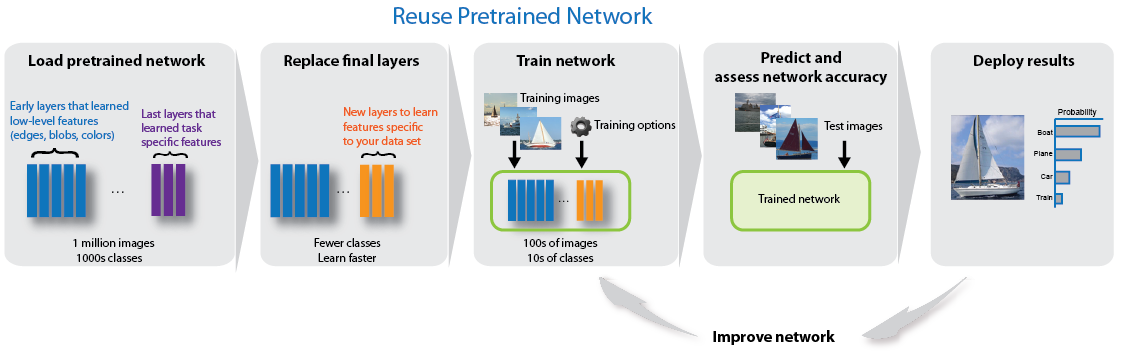

## Load Data

imds = imageDatastore('dataset\2701_Section_Categories\Section1', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
imds.ReadFcn = @customreader;
info= countEachLabel(imds);
[imds1,imds2]=splitEachLabel(imds,min(info{:,2}),'randomized');

## Visualize the dataset

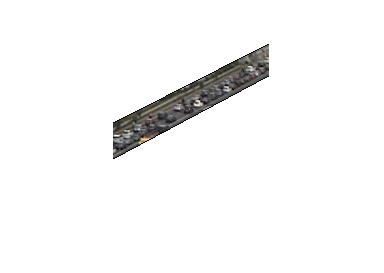

numImages = numel(imds.Labels);
idx = randperm(numImages,1);
figure
I = readimage(imds,idx);
imshow(I)

## Train the Neural Network

deepnetworkdesigner

## Classify Validation Images

[YPred,scores] = classify(trainedNetwork_1,imds);

Repeat process above to get 4 neural networks for different sections.

## Display four sample validation images with their predicted labels.

idx = randperm(numel(imds.Files),1);
imds.Files(idx);

ans = 1×1 cell array
    {'C:\Users\KevinChng\Desktop\NUS Project\Singapore to Jb\Copy_of_2701_Categories\Traffic Jam\Jan_2701_26T11_45_00.png.png'}


I = readimage(imds,idx);
W1 = imcrop(I,[480 59.5 155 137]);
W1 = imresize(W1,[227 227]);
W2 = imcrop(I,[320 113.5 160 181]);
W2 = imresize(W2,[227 227]);
W3 = imcrop(I,[160 185.5 320 181]);
W3 = imresize(W3,[227 227]);
W4 = imcrop(I,[2 266.5 160 140]);
W4 = imresize(W4,[227 227]);
[YPred1,scores1] = classify(net,W1)

YPred1 = categorical
     2 


scores1 = 1×2 single row vector
    0.0010    0.9990


[YPred2,scores2] = classify(network2,W2)

YPred2 = categorical
     Crop2_Traffic Jam 


scores2 = 1×2 single row vector
    0.0000    1.0000


[YPred3,scores3] = classify(network3,W3)

YPred3 = categorical
     Crop3_Traffic Jam 


scores3 = 1×2 single row vector
    0.0000    1.0000


[YPred4,scores4] = classify(network4,W4)

YPred4 = categorical
     Crop4_Traffic Jam 


scores4 = 1×2 single row vector
    0.0027    0.9973


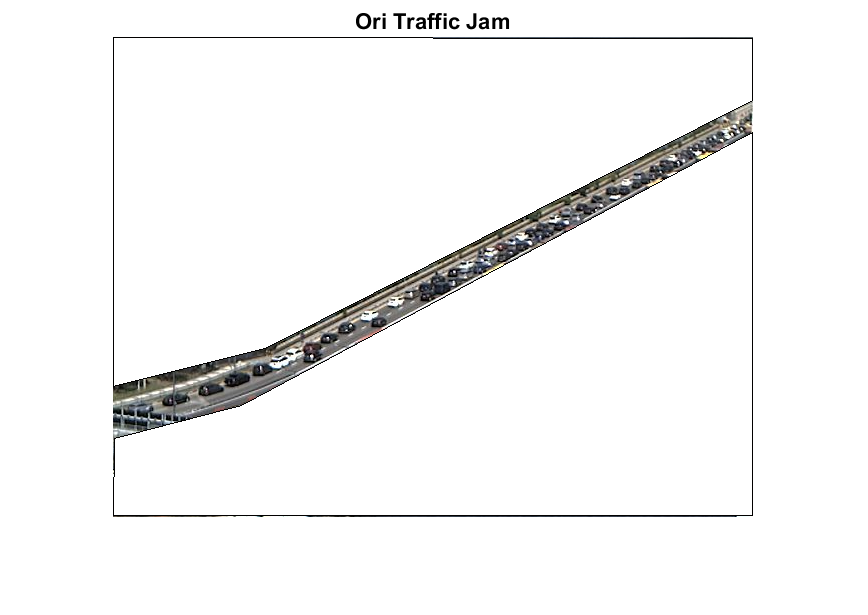

imshow(I)
title(sprintf("Ori %s",string(imds.Labels(idx))));

Calculate the classification accuracy on the validation set. Accuracy is the fraction of labels that the network predicts correctly.

YValidation = imds.Labels;
%accuracy = mean(YPred == YValidation)

For tips on improving classification accuracy, see [Deep Learning Tips and Tricks](docid:nnet_ug#mw_b35bb367-38bf-4597-8e6b-479a2b3c408e).

*Copyright 2020 Kevin Chng, TechSource System*

function X = customreader(filename)
    X = imread(filename);
    X = imresize(X,[227 227]);
end